clear;clc;close all

## First load some data

rng default  % For reproducibility
load kmeansdata
size(X)

ans =    560     4


Even though these data are four-dimensional, and cannot be easily visualized, kmeans enables you to investigate whether a group structure exists in them. Call kmeans with k, the desired number of clusters, equal to 3. For this example, specify the city block distance measure, and use the default algorithm for cluster center initialization.

idx3 = kmeans(X,3,'Distance','cityblock');

## How well separated are the clusters

To get an idea of how well-separated the resulting clusters are, you can make a silhouette plot using the cluster indices output from kmeans. The silhouette plot displays a measure of how close each point in one cluster is to points in the neighboring clusters. This measure ranges from +1, indicating points that are very distant from neighboring clusters, through 0, indicating points that are not distinctly in one cluster or another, to -1, indicating points that are probably assigned to the wrong cluster. silhouette returns these values in its first output.

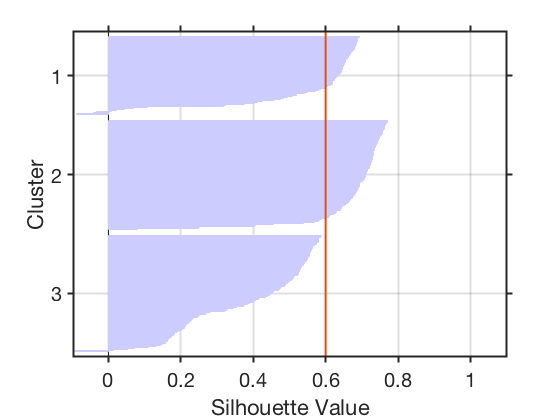

figure
[silh3,h] = silhouette(X,idx3,'cityblock');
h = gca;
h.Children.EdgeColor = [.8 .8 1];
yl=ylim;hold on;plot([0.6 0.6],yl,'LineWidth',2)
xlabel 'Silhouette Value'
ylabel 'Cluster'
grid on
set(gca,'FontSize',20); set(gca,'TickDir','out'); set(gca,'LineWidth',2);
print('-depsc2','Silhouette-3.eps');% save to an eps file

From the silhouette plot, you can see that most points in the second cluster have a large silhouette value, greater than 0.6, indicating that the cluster is somewhat separated from neighboring clusters. However, the third cluster contains many points with low silhouette values, and the first and third contain a few points with negative values, indicating that those two clusters are not well separated.